## This MATLAB program generates Table 6 of Vrugt, WRR (2024) 

Mean Values of the Quadratic, Logarithmic, Spherical, Continuous Ranked Probability, and Linear Scoring Rules for Distribution Forecasts, P1 = U(0.11,3.89), P2 = N(2.26,1.52), P3 = GEV(0.04,1,1.86), P4 = LN(0.80,0.26) and P5 = GP(0.28,2,0.73) Displayed in Figure 2a

**Reference**:

Vrugt, J. A. (2024). **Distribution-based model evaluation and diagnostics: Elicitability, propriety, and scoring rules for hydrograph functionals**. *Water Resources Research*, 60,e2023WR036710, [https://doi.org/10.1029/2023WR036710](https://doi.org/10.1029/2023WR036710)

Written by **Jasper A. Vrugt**

**Define Q: Gamma distribution**

close all hidden; clear variables

% Fig. 2a: Distributions with an equal coefficient of variation
x_max = 20;                     % maximum value of x
x = linspace(0,x_max,601)';     % discrete x using equally-spaced values
% Lets assume that true distribution is a gamma pdf
lq = 0.5; plq = 0.025;          % at 2.5%
uq = 5.0; puq = 0.975;          % at 97.5%
% Find the coefficients that create this distribution
cG = fminsearch(@(cG) sum((gaminv([plq puq],cG(1),cG(2)) - [lq uq]).^2),[20 5]);
% What is now the CV? Numerical estimate - may be inaccurate!
X = gamrnd(cG(1),cG(2),1e6,1); CVgam = std(X)/mean(X);

**Define P1,...,P6: Distributions with the exact same CV as P1**

P1: Uniform distribution 

P2: Normal distribution

P3: Generalized Extreme Value distribution

P4: Lognormal distribution 

P5: Generalized Pareto distribution  

muU = 2; stdU = muU*CVgam;                  % If we fix mean of distribution to 2
wdth = stdU/sqrt(1/12);                     % Thus to get CV of CVgam we need
                                            % Theory: Width of 1 ==> std = sqrt(1/12)
m_a = muU - 1/2*wdth; m_b = muU + 1/2*wdth; % Ranges of uniform distribution
gPsetting = 2.0;                            % Parameter of Generalized Pareto distribution
% P2: Normal distribution
[cN,errCN_a] = fminsearch(@(x) fit_pdf(x,2,CVgam,gPsetting),[3 1]); 
cN = [2.26 sqrt(1.52)];
% P3: Generalized Extreme Value distribution?
[cGEV,errGEV_a] = fminsearch(@(x) fit_pdf(x,3,CVgam,gPsetting),[0.1 1.2]);
% P4: Lognormal distribution?
[cLN,errLN_a] = fminsearch(@(x) fit_pdf(x,4,CVgam,gPsetting),[0.6 1.5]); 
cLN = [0.8011 0.5141]; 
% P5: Generalized Pareto distribution
[cGP,errGP_a] = fminsearch(@(x) fit_pdf(x,5,CVgam,gPsetting),[0.2 0.15]); 
cGP = [-0.2792    0.7294];
% print residual^2 to make sure that CV of each distribution is essentially identical
%[0 errCN_a errGEV_a errLN_a errGP_a]

**Plot all the distributions**

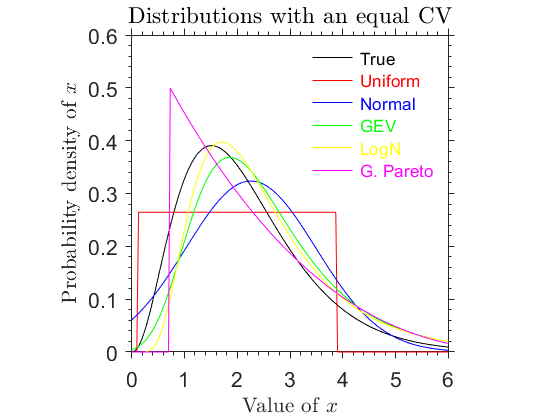

figure(1)
% true distribution Q
plot(x,gampdf(x,cG(1),cG(2)),'k'); hold on
% Uniform distribution: red
plot(x,unifpdf(x,m_a,m_b),'r');
% Now normal distribution: blue
plot(x,normpdf(x,cN(1),cN(2)),'b');
% Generalized Extreme Value: green
plot(x,gevpdf(x,cGEV(1),1,cGEV(2)),'g');
% Lognormal distribution: yellow
plot(x,lognpdf(x,cLN(1),cLN(2)),'y');
% Generalized Pareto distribution: magenta
plot(x,gppdf(x,cGP(1),2,cGP(2)),'m');
legend({'\color{black} True','\color{red} Uniform','\color{blue} Normal',...
    '\color{green} GEV','\color{yellow} LogN','\color{magenta} G. Pareto'},'fontsize',13,...
    'box','off')
title('Distributions with an equal CV','fontsize',16,'interpreter','latex');
set(gca,'tickdir','out','TickLength',[0.02 0.04],'XMinorTick','on','YMinorTick','On',...
    'fontsize',16,'xtick',[0:6],'xticklabel',[0:6]);
axis([0 6 0 0.6]); axis square
xlabel('Value of $x$','fontsize',16,'interpreter','latex');
ylabel('Probability density of $x$','fontsize',16,'interpreter','latex');

**Initialization: Now let's evaluate the scoring rules of a density forecast**

% We sample nq times from P1m the gamma distribution. These are values of w_1,...,w_n
nq = 1e4;                           % number of draws from true distribution Q
xq = gamrnd(cG(1),cG(2),nq,1);      % realizations, xq, of true distribution Q
np = 1e6;                           % number of samples from P for norm(P) determination 
xpmin = -1e2; xpmax = 1e2;          % grid for numerical integration  
M = 10000;                          % number of samples for CRPS
% The α-norm of a μ-density p is defined as (\int_{-infty}^infty p^α dμ)^1/α,
% for a Lebsgue density simplying to (\int_{-infty}^infty p(x)^α d(x))^1/α.  
% Based on the collection of densities under consideration, we cannot use 0 as lowerbound.
% Lower and upperbound should be taken such that the p(x) integrates to 1 on [xpmin,xpmax]
% We can print the 1-norm to verify whether we x_max2 is large enough
xp = linspace(xpmin,xpmax,np);       % sampled values: equally spaced
nP = 6;                              % number of distributions P we test
deltax = (xpmax-xpmin)/np;           % Δx
fP = nan(np,nP); fPQ = nan(nq,nP);
[QSz,LSz,SSz,CRPSz,LinSz] = ...
    deal(nan(nq,nP)); X = nan(M,nP);
pdf_norm = nan(1,nP);

**Now evaluate samples using scoring rules**

for z = 1:nP % Loop over distribution
    switch z
        case 1 % True distribution Q: plot(x,gampdf(x,cG(1),cG(2)),'k');
             fP(1:np,z) = gampdf(xp,cG(1),cG(2));
             fPQ(1:nq,z) = gampdf(xq,cG(1),cG(2));
             X(1:M,z) = gamrnd(cG(1),cG(2),M,1);                % For CRPS
        case 2 % Uniform distribution: plot(x,unifpdf(x,m_a,m_b),'r');
             fP(1:np,z) = unifpdf(xp,m_a,m_b); 
             fPQ(1:nq,z) = unifpdf(xq,m_a,m_b);
             X(1:M,z) = unifrnd(m_a,m_b,M,1);                   % For CRPS
        case 3 % Normal distribution: plot(x,normpdf(x,cN(1),cN(2)),'b');
             fP(1:np,z) = normpdf(xp,cN(1),cN(2)); 
             fPQ(1:nq,z) = normpdf(xq,cN(1),cN(2));
             X(1:M,z) = normrnd(cN(1),cN(2),M,1);               % For CRPS
        case 4 % Generalized Extreme Value: plot(x,gevpdf(x,cGEV(1),1,cGEV(2)),'g');
             fP(1:np,z) = gevpdf(xp,cGEV(1),1,cGEV(2)); 
             fPQ(1:nq,z) = gevpdf(xq,cGEV(1),1,cGEV(2));
             X(1:M,z) = gevrnd(cGEV(1),1,cGEV(2),M,1);          % For CRPS
        case 5 % Lognormal distribution: plot(x,lognpdf(x,cLN(1),cLN(2)),'y');
             fP(1:np,z) = lognpdf(xp,cLN(1),cLN(2)); 
             fPQ(1:nq,z) = lognpdf(xq,cLN(1),cLN(2));
             X(1:M,z) = lognrnd(cLN(1),cLN(2),M,1);             % For CRPS
        case 6 % Pareto distribution: plot(x,gppdf(x,cGP(1),gPsetting,cGP(2)),'m');
             fP(1:np,z) = gppdf(xp,cGP(1),gPsetting,cGP(2)); 
             fPQ(1:nq,z) = gppdf(xq,cGP(1),gPsetting,cGP(2));  
             X(1:M,z) = gprnd(cGP(1),gPsetting,cGP(2),M,1);     % For CRPS
    end
    % Compute norm of forecast density P
    sum(fP(1:np,z)* deltax)                                     % check norm_1 pdf = 1
    pdf_norm(1,z) = sqrt(sum(fP(1:np,z).^2) * deltax);          % 2-norm
    % Now compute scoring rules [density forecasts]
    QSz(1:nq,z) = 2*fPQ(1:nq,z) - pdf_norm(1,z)^2;
    LSz(1:nq,z) = log2(fPQ(1:nq,z));
    SSz(1:nq,z) = fPQ(1:nq,z) / pdf_norm(1,z);
    LinSz(1:nq,z) = fPQ(1:nq,z);
    % Now the CRPS: numerically
    for ii = 1:nq
        CRPSz(ii,z) = crp_score(X(1:M,z)',xq(ii),'weib');
    end
end

ans = 1.0000

ans = 1.0000

ans = 1.0000

ans = 1.0000

ans = 1.0000

ans = 1.0000

% Take the sum of the scoring rules z
QS = sum(QSz); LS = sum(LSz); SS = sum(SSz); LinS = sum(LinSz); CRPS = sum(CRPSz);
% Group for Table and define score_names
V = [ QS; LS ; SS ; CRPS ; LinS ]/nq; score_names = {'QS','LS','SS','CRPS','LinS'};
% Now print a Table
fprintf('\n');
fprintf('______________________________________________________________________________ \n');

______________________________________________________________________________ 


fprintf('Table 6: Mean value quadratic, logarithmic, spherical and linear scoring rules \n');

Table 6: Mean value quadratic, logarithmic, spherical and linear scoring rules 


fprintf('______________________________________________________________________________ \n');

______________________________________________________________________________ 


fprintf('            P1        P2        P3       P4        P5       P = Q  \n');

            P1        P2        P3       P4        P5       P = Q  


fprintf('Score      unif      norm      gev      logn       gp       gamma  \n');

Score      unif      norm      gev      logn       gp       gamma  


fprintf('       ___________________________________________________________ \n');

       ___________________________________________________________ 


for i = 1:size(V,1)
    fprintf('%-6s  %7.3f   %7.3f   %7.3f   %7.3f   %7.3f   %7.3f \n', ...
        char(score_names(i)),[ V(i,2:size(V,2)) V(i,1)]);
end

QS        0.218     0.243     0.256     0.257     0.246     0.270 
LS         -Inf    -2.302    -2.215    -2.293      -Inf    -2.138 
SS        0.469     0.494     0.506     0.507     0.498     0.520 
CRPS     -0.660    -0.662    -0.673    -0.672    -0.651    -0.646 
LinS      0.241     0.236     0.251     0.260     0.269     0.271 


fprintf('       ___________________________________________________________ \n');

       ___________________________________________________________ 


fprintf('Note:  1. Scoring functions are defined as reward functions \n');

Note:  1. Scoring functions are defined as reward functions 


fprintf('______________________________________________________________________________ \n');

______________________________________________________________________________ 


**Now create Table 6 in Latex for paper**

fprintf('Table 6\n')

Table 6


scores = {'\text{QS}','\text{LS}','\text{SS}','\text{CRPS}','\text{LinS}'};
Vall = V;
for tt = 1:5
    V = Vall(tt,:);
    id = V > 0; T1 = [];
    for i = 1:numel(V)
        if V(i) > 0
            T1{i} = '\hphantom{-}';
        else
            T1{i} = '-';
        end
    end
    V = abs(V);
    fprintf(['%s & %s$%5.3f$ & %s$%5.3f$ & %s$%5.3f$ & %s$%5.3f$ & %s$%5.3f$ && ' ...
        '%s$%5.3f$ \\\\ \n'],char(scores(tt)), ...
        char(T1(2)) , V(2) , ...
        char(T1(3)) , V(3) , ...
        char(T1(4)) , V(4) , ...
        char(T1(5)) , V(5) , ...
        char(T1(6)) , V(6) , ...
        char(T1(1)) , V(1) );
end

\text{QS} & \hphantom{-}$0.218$ & \hphantom{-}$0.243$ & \hphantom{-}$0.256$ & \hphantom{-}$0.257$ & \hphantom{-}$0.246$ && \hphantom{-}$0.270$ \\ 
\text{LS} & -$  Inf$ & -$2.302$ & -$2.215$ & -$2.293$ & -$  Inf$ && -$2.138$ \\ 
\text{SS} & \hphantom{-}$0.469$ & \hphantom{-}$0.494$ & \hphantom{-}$0.506$ & \hphantom{-}$0.507$ & \hphantom{-}$0.498$ && \hphantom{-}$0.520$ \\ 
\text{CRPS} & -$0.660$ & -$0.662$ & -$0.673$ & -$0.672$ & -$0.651$ && -$0.646$ \\ 
\text{LinS} & \hphantom{-}$0.241$ & \hphantom{-}$0.236$ & \hphantom{-}$0.251$ & \hphantom{-}$0.260$ & \hphantom{-}$0.269$ && \hphantom{-}$0.271$ \\ 


fprintf('\n'); fprintf('\n');